# Covid classification - CRNN

remove previous data

close all; clc; clear;

choose gpu

gpu_selected = "0"; % "0" | "1" | "no"
select_gpu(gpu_selected);

gpu 0


load ds

% [Features, trueLabels, adsSpecs, win_info] = load_ds(); % for 1st time only
load ds;

% save original data (just in case)
Features_orig = Features;
trueLabels_orig = trueLabels;

reduce No. sequences

% seq_th = 20;
% NUM_SEQ = zeros(length(Features), 1);
% 
% for i = 1 : length(Features)
%     num_seq = size(Features{i}, 4);
%     NUM_SEQ(i) = num_seq;
% %     Features{i} = Features{i}(:,:,:, 1 : min(num_seq, seq_th));
% end

shuffle and split data into train val test

shuffle_ds = "TrainVal"; % "yes" | "no" | "TrainVal"
balance_ds = "TrainVal"; % "yes" | "no" | "TrainVal"
split_prcnts = [0.6 0.2 0.2]; % size of train val test in [%]
[FeaturesTrain, trueLabelsTrain, FeaturesVal, trueLabelsVal, FeaturesTest, trueLabelsTest] = ...
    split_shuffle_ds(Features, trueLabels, shuffle_ds, balance_ds, split_prcnts);

choose hyper-parameters

% CNN
net_cnn_name = "vggish";
freeze_layers_cnn = "no";
add_fc_layer_cnn = "no";
cnn_fc_outputSize = 2048;

% LSTM
numHiddenUnits = 1024;
drop_prob = 0.1; % 0.05 0.1 0.15 0.2 0.25

% training options
MaxEpochs = 20;
miniBatchSize = 4;
InitialLearnRate = 0.0001;
L2Regularization = 0.003;
LearnRateSchedule = "piecewise"; % "none" "piecewise"
LearnRateDropPeriod = 1; % 1 2
LearnRateDropFactor = 0.9;
ValidationPatience = 10; % 5 | positive integer | Inf
SequencePaddingDirection = "right"; % "right" "left"
SequenceLength = "longest"; % "longest" (default) | "shortest" | positive integer
checkpointPath = "checkpoint"; % save net in folder after each epoch

set classes and classes weights

uniqueLabels = unique(trueLabelsTrain); % ["negative" "positive"]
numClasses = 2;
num_train_pos = sum(trueLabelsTrain == "positive");
num_train_neg = sum(trueLabelsTrain == "negative");
num_train = num_train_pos + num_train_neg;
classWeightsUniform = 'none';

% give weight to each class by the other one relative size
% classWeightsBalanced = [num_train_pos, num_train_neg] / num_train; % my original method
classWeightsBalanced = num_train ./ ([num_train_neg num_train_pos] * numClasses);

classWeights = classWeightsBalanced;
disp([num2str(num_train_pos), ' ', num2str(num_train_neg)]);

439 439


load relevent layers from pre-traind CNN network (yamnet/vggish)

lgraph_cnn = load_cnn_lgraph(net_cnn_name, freeze_layers_cnn);

create LSTM network

numClasses = 2; % No. classes

lstmLayers = [
    bilstmLayer(numHiddenUnits, 'OutputMode', 'last', 'Name', 'bilstm')
    dropoutLayer(drop_prob, 'Name', 'drop')
    fullyConnectedLayer(numClasses, 'Name', 'fc_lstm2')
    softmaxLayer('Name', 'softmax')
    classificationLayer("Name", "classification", "Classes", uniqueLabels, "ClassWeights", classWeights)
    ];

add fully connected layer to CNN

if net_cnn_name == "vggish" && add_fc_layer_cnn == "yes"

    last_layer_name = string(lgraph_cnn.Layers(end, 1).Name); % save name of last orig layer

    % create extra fc layers
    layers = [
        fullyConnectedLayer(cnn_fc_outputSize, 'Name', 'fc_cnn_last')
        reluLayer('Name', 'activation_cnn_last')
        ];

    % add and connect extra layers (fc, BN, relu) to end of cnn
    lgraph_cnn = addLayers(lgraph_cnn, layers);
    lgraph_cnn = connectLayers( ...
        lgraph_cnn, ...
        last_layer_name, ...
        'fc_cnn_last');
end

assemble CNN and LSTM networks

lstm input -> folding -> CNN -> unfolding -> lstm -> classification

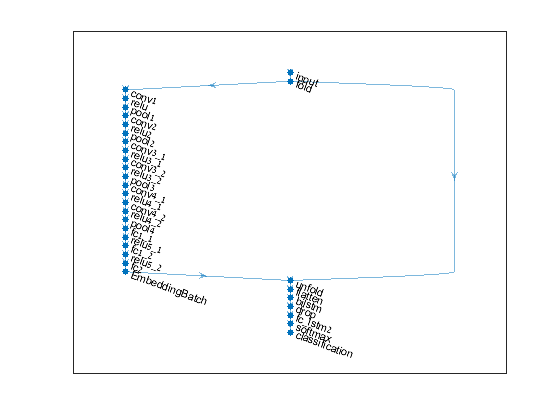

% create empty layer graph
lgraph_crnn = layerGraph;

% add new input layer (sequence input for lstm) and folding layer
inputSize = [96 64]; % input size needs to be the same as for CNN
layers = [
    sequenceInputLayer([inputSize 1], 'Name', 'input') % sequence input for lstm
    sequenceFoldingLayer('Name', 'fold') % change structure for CNN
    ];

% connect new input layers to input of CNN
lgraph_crnn = addLayers(lgraph_crnn, layers);
lgraph_crnn = addLayers(lgraph_crnn, lgraph_cnn.Layers);
lgraph_crnn = connectLayers(lgraph_crnn, "fold/out", string(lgraph_cnn.Layers(1, 1).Name));

% add unfolding and lstm layers
layers = [
    sequenceUnfoldingLayer('Name', 'unfold') % change structure back for lstm
    flattenLayer('Name', 'flatten') % change dim from [1, 1, No. output features] to [No. output features, 1]
    lstmLayers
    ];

% connect unfolding and lstm layers to output of CNN
lgraph_crnn = addLayers(lgraph_crnn, layers);
lgraph_crnn = connectLayers(lgraph_crnn, string(lgraph_cnn.Layers(end, 1).Name), "unfold/in");

% add parallel connection between folding & unfolding layers (needed to restore the sequence structure)
lgraph_crnn = connectLayers(lgraph_crnn, "fold/miniBatchSize", "unfold/miniBatchSize");

% analyze network
figure;
plot(lgraph_crnn);

% analyzeNetwork(lgraph);

specify training options

numObservations = numel(FeaturesTrain);
validationFrequency = floor(numObservations / miniBatchSize);

options = trainingOptions( ...
    'adam', ...
    'Plots', 'training-progress', ... % 'none' (default) | 'training-progress'
    'Verbose', true, ... % 1 (true) (default) | 0 (false)
    'MaxEpochs', MaxEpochs, ...
    'MiniBatchSize', miniBatchSize, ...
    'Shuffle', 'every-epoch', ... % 'once' (default) | 'never' | 'every-epoch'
    'ExecutionEnvironment', 'auto', ... % 'auto' (default) | 'cpu' | 'gpu' | 'multi-gpu' | 'parallel'
    ...
    'ValidationData', {FeaturesVal, trueLabelsVal}, ...
    'ValidationFrequency', validationFrequency, ...
    'InitialLearnRate', InitialLearnRate, ...
    'LearnRateSchedule', 'piecewise', ... % piecewise, none
    'LearnRateDropPeriod', 1, ...
    'LearnRateDropFactor', LearnRateDropFactor, ...
    'L2Regularization', L2Regularization, ...
    'ValidationPatience', ValidationPatience, ...
    ...
    'SequencePaddingDirection', SequencePaddingDirection, ...
    'SequenceLength', SequenceLength, ...% "longest" (default) | "shortest" | positive integer
    ...
    'CheckpointPath', checkpointPath, ...
    'BatchNormalizationStatistics', 'moving' ... % 'population' (default) | 'moving'
    );

Train the LSTM network with the specified training options.

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:26 |       25.00% |       50.00% |       0.6981 |       0.6944 |      1.0000e-04 |
|       1 |          50 |       00:00:52 |       75.00% |              |       0.6629 |              |      1.0000e-04 |
|       1 |         100 |       00:01:16 |       50.00% |              |       0.7209 |              |      1.0000e-04 |
|       1 |         150 |       00:01:42 |      100.00% |              |       0.6349 |              |      1.0000e-04 |
|       

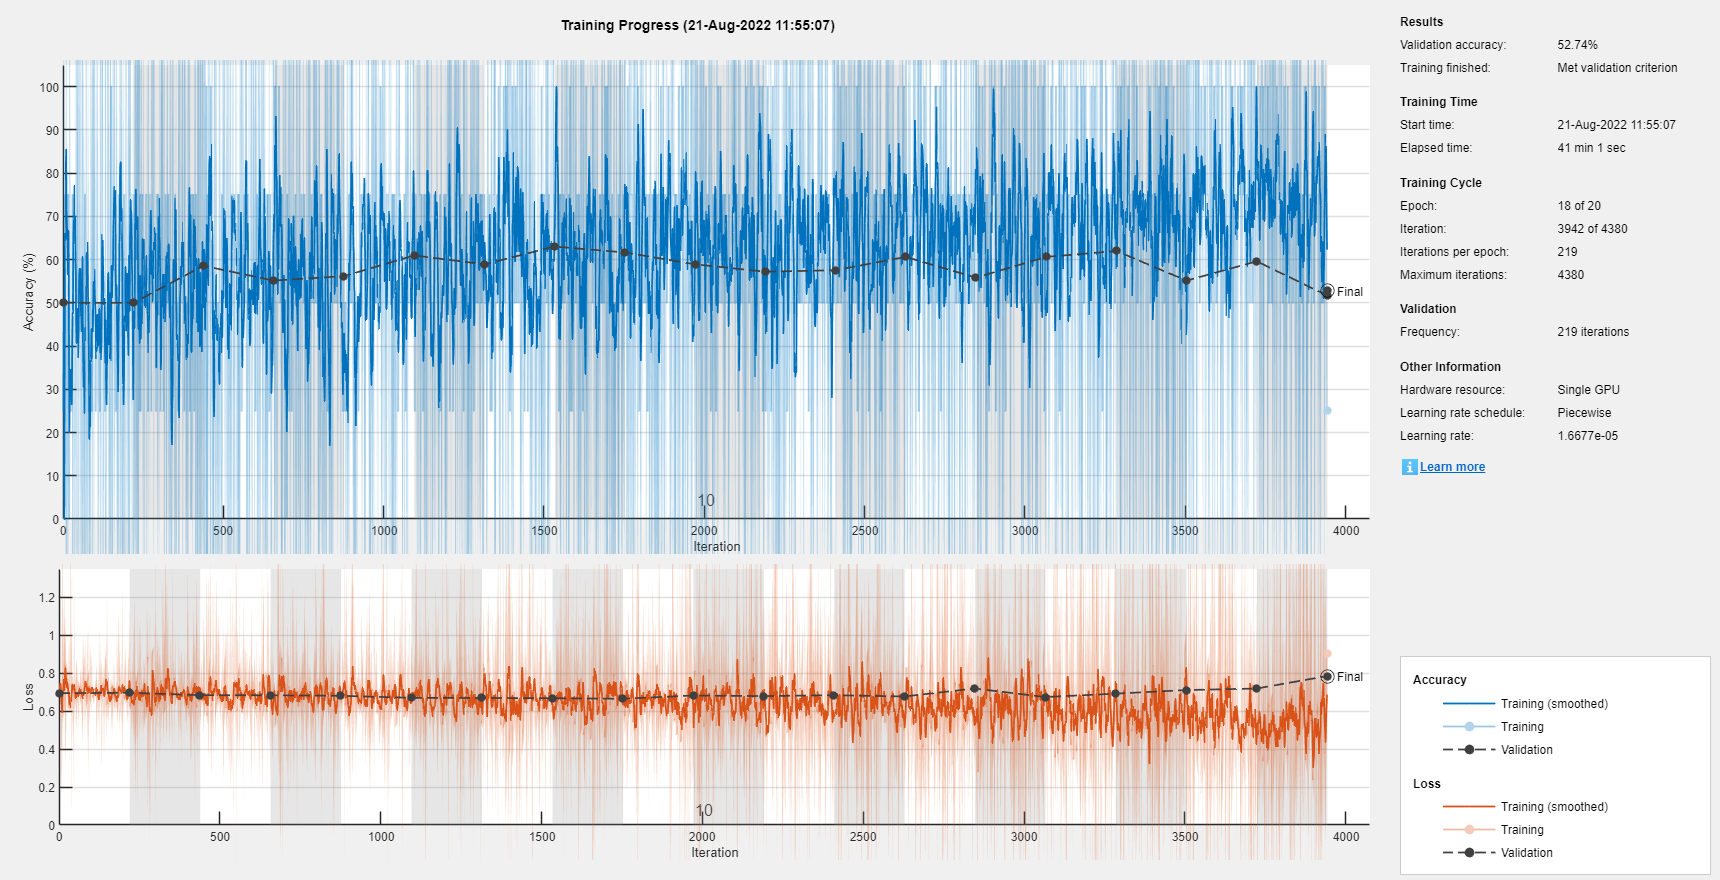

% remove saved nets from previous training
delete(checkpointPath + "/*");

% train network
[net, net_info] = trainNetwork(FeaturesTrain, trueLabelsTrain, lgraph_crnn, options);

load net (out of all nets yelded from current training) from epoch with best result (lowest validation error)

net_classification_CRNN = extract_net_from_checkpoint(net_info, checkpointPath);
% net_classification_CRNN = net;

predict on train, val and test sets (probability [0,1]).

% miniBatchSize_predict = miniBatchSize;
miniBatchSize_predict = 1;
positive_indx = find(string(uniqueLabels) == "positive");
predLabelsTrain = predict(net_classification_CRNN, FeaturesTrain, 'MiniBatchSize', miniBatchSize_predict);
predLabelsTrain = predLabelsTrain(:, positive_indx);
predLabelsVal   = predict(net_classification_CRNN, FeaturesVal, 'MiniBatchSize', miniBatchSize_predict);
predLabelsVal   = predLabelsVal(:, positive_indx);
predLabelsTest  = predict(net_classification_CRNN, FeaturesTest, 'MiniBatchSize', miniBatchSize_predict);
predLabelsTest  = predLabelsTest(:, positive_indx);

find best ROC thrshold on val set, and plot ROC curve

plot ROC curve and confusion matrix on test set.

display for train, val and test sets:

- ROC & AUC

- confusion matrix

- accuracy, UAR (unweighted average recall), F1 score, sensetivity, PPV, specificity

accuracy = (TP + TN) / (TP + TN + FP + FN)

UAR = (sensetivity + specificity) / 2

F1-score = 2 * (PPV * sensitivity) / (PPV + sensitivity)

sensitivity = TP / (TP + FN)

PPV = TP / (TP + FP)

specificity = TN / (TN + FP)

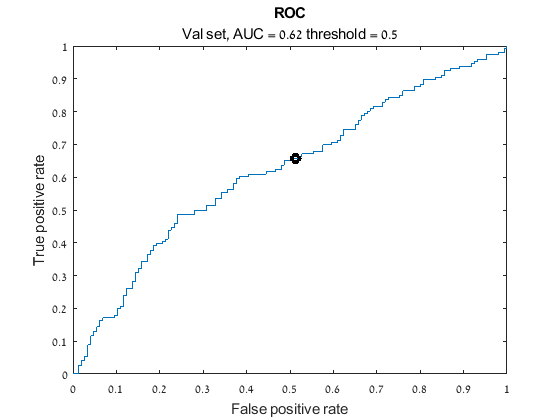

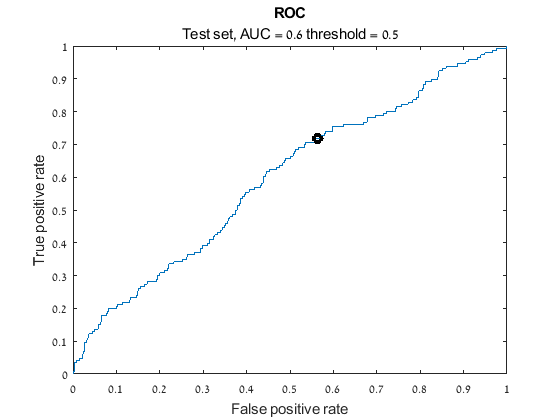

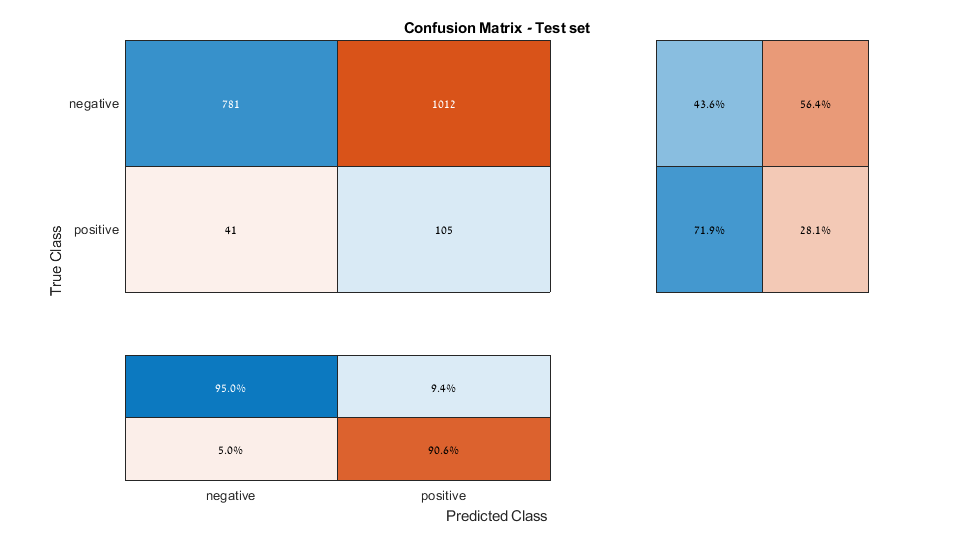

scores:
             accuracy [%]    UAR [%]    F1 [%]    sensitivity [%]    PPV [%]    specificity [%]
             ____________    _______    ______    _______________    _______    _______________

    train        62.5         62.5         66          72.7           60.4           52.4      
    val          57.2         57.2       60.6          65.8           56.1           48.6      
    test         45.7         57.7       16.6          71.9            9.4           43.6      



roc_threshold = 0.5; % choose threshold for ROC curve

extract_scores_classification_CRNN( ...
    {predLabelsTrain predLabelsVal predLabelsTest}, ...
    {trueLabelsTrain trueLabelsVal trueLabelsTest}, ...
    net_cnn_name, ...
    roc_threshold ...
    );

deselects the GPU device and clears its memory

gpuDevice([]);